hcn = 12; %number of HC subjects
hcss = 2; %number of sessions for HC subjects
msn = 12; %number of MS patients
msss = 5; %number of sessions for MS patients

IF YOU WANT TO USE DIRECTLY THE RESULTS FROM THE rDCM WITHOUT COMPUTING THEM, AFTER HAVING RUNNED THIS SECTION SKIP DIRECTILY TO SECTION (B)

(A) LOAD DATA OF HC SESSIONS 1-2 INTO CELL ARRAY HCs

%load healthy controls session 1 and 2
dataFolder = "\Data_preprocessed\";
HCs = cell(hcss,hcn);
for i = 1:hcn
    dir1 = sprintf("HC\\Subject%03d\\ROI_Subject%03d_Session001.mat",i,i);
    dir2 = sprintf("HC\\Subject%03d\\ROI_Subject%03d_Session002_new.mat",i,i);
    m1 = matfile(join([dataFolder,dir1],""));
    m2 = matfile(join([dataFolder,dir2],""));
    HCs{1,i} = m1.data;
    HCs{2,i} = m2.data;
end


RUN ONLY ONE TIME TO CHANGE THE NAMES OF THE FILES FOR MS

dataFolder = "\Data_preprocessed\";
%change name of files so that they make sense buoy
for k=1:msn
for i= 1:msss
    oldfilename = sprintf("MS\\Pat%03d\\ROI_Subject%03d_Session001.mat",k,i);
    newfilename = sprintf("MS\\Pat%03d\\ROI_pat%03d_Session%03d.mat",k,k,i);
    if ~isequal(newfilename, oldfilename)
        movefile(join([dataFolder,oldfilename],""),join([dataFolder,newfilename],""))
    end
    
end
end

Unrecognized function or variable 'msn'.

LOAD MS PATIENTS DATA SESSIONS 1-5 INTO CELL ARRAY MSs

%LOAD MS PATIENTS SESSIONS 1-5
MSs = cell(msss,msn);
dataFolder = "\Data_preprocessed\";
for k=1:msn
    for i=1:msss
        path = sprintf("MS\\Pat%03d\\ROI_pat%03d_Session%03d.mat",k,k,i);
        mfile = matfile(join([dataFolder,path],""));
        MSs{i,k} = mfile.data;
    end
end

RUN TAPAS rDCM ESTIMATION FOR HCs, FULLY CONNECTED,BOTH SPARSE AND NON SPARSE

%define fully connectected DCM structure with parameters, data inserted
%in the loop
DCMfc.a = ones(7);
DCMfc.b = [];
DCMfc.c = [];
DCMfc.d = [];
DCMfc.options.nonlinear = 0; 
DCMfc.options.two_state = 0;
DCMfc.options.stochastic = 0;
DCMfc.options.centre = 1;
DCMfc.options.induced = 1;
DCMfc.n = 7;
DCMfc.Y.dt = 3;

HCconnections_ns = cell(hcss,hcn); %non sparse 
HCconnections = cell(hcss,hcn); % sparse 
for k = 1:hcn
    for i = 1:hcss
       DCMfc.Y.y = HCs{i,k};
       [output1] = tapas_rdcm_estimate(DCMfc, 'r', [], 1); %non sparse
       [output2] = tapas_rdcm_estimate(DCMfc, 'r', [], 2); %sparse
       HCconnections_ns{i,k} = output1;
       HCconnections{i,k} = output2;
    end
end

%save cell arrays with resulting structs
save ns_connectionsHC.mat HCconnections_ns
save connectionsHC.mat HCconnections

RUN TAPAS rDCM FOR MS PATIENTS, FULLY CONNECTED, BOTH SPARSE AND NON SPARSE

%define fully connectected DCM structure with parameters, data inserted
%in the loop
DCMfc.a = ones(7);
DCMfc.b = [];
DCMfc.c = [];
DCMfc.d = [];
DCMfc.options.nonlinear = 0; 
DCMfc.options.two_state = 0;
DCMfc.options.stochastic = 0;
DCMfc.options.centre = 1;
DCMfc.options.induced = 1;
DCMfc.n = 7;
DCMfc.Y.dt = 3;

MSconnections_ns = cell(msss, msn);
MSconnections = cell(msss, msn);

for k = 1:msn
    for i = 1:msss
       k,i
       DCMfc.Y.y = MSs{i,k};
       [output1] = tapas_rdcm_estimate(DCMfc, 'r', [], 1); %non sparse
       [output2] = tapas_rdcm_estimate(DCMfc, 'r', [], 2); %sparse
       MSconnections_ns{i,k} = output1;
       MSconnections{i,k} = output2;
    end
end

%save cell arrays with resulting struct
save ns_connectionsMS.mat MSconnections_ns
save connectionsMS.mat MSconnections


(B) DEFINE CELL ARRAYS FOR CONNECTIVITY MATRICES AND NODE STRENGTHS

%get A (connectivity) matrices and node strengths
HCA_mat_ns = cell(hcss,hcn); %carrays with all A-matrices non sparse
MSA_mat_ns = cell(msss,msn);
HCA_mat = cell(hcsss,hcn); %carrays with A matrices sparse
MSA_mat = cell(msss,msn);
HCnode_strengths_ns = cell(hcss,hcn); %carrays with node strength non sparse
MSnode_strengths_ns = cell(msss,msn); 
HCnode_strengths = cell(hcss,hcn); %carrays with node strength sparse
MSnode_strengths = cell(msss,msn); 

Compute node strengths for HC/MS Sparse/NonSparse

A = ones(7) -eye(7);

for row=1:hcss
    for column=1:hcn
        HCA_mat{row,column} = HCconnections{row,column}.Ep.A;
        hca = A.*HCA_mat{row,column};
        HCnode_strengths{row,column} = sum(hca,1) + sum(hca,2)';
        HCA_mat_ns{row,column} = HCconnections_ns{row,column}.Ep.A;
        hca_ns = A.*HCA_mat_ns{row,column};
        HCnode_strengths_ns{row,column} = sum(hca_ns,1) + sum(hca_ns,2)';   
    end
end



for row=1:msss
    for column=1:msn
        MSA_mat{row,column} = MSconnections{row,column}.Ep.A;
        msa = A.*MSA_mat{row,column};
        MSnode_strengths{row,column} = sum(msa,1) + sum(msa,2)';
        MSA_mat_ns{row,column} = MSconnections_ns{row,column}.Ep.A;
        msa_ns = A.*MSA_mat_ns{row,column};
        MSnode_strengths_ns{row,column} = sum(msa_ns,1) + sum(msa_ns,2)';
    
    end
end



Compute mean of strength over subjects MS/HC Sparse/NonSparse

%get mean (over patients) of node strength for each region/session 
MS_mean = cell(msss,1);
HC_mean =  cell(hcss,1);
MS_ns_mean = cell(msss,1);
HC_ns_mean =  cell(hcss,1);

for i=1:msss
    sum = 0;
    sumns = 0;
    for m = 1:msn
        sum = sum + MSnode_strengths{i,m};
        sumns = sumns +MSnode_strengths_ns{i,m};
    end
    MS_ns_mean{i} = sum / msn;
    MS_mean{i} = sumns /msn;
end

for i=1:hcss
    sum = 0;
    sumns = 0;
    for m = 1:hcn
        sum = sum + HCnode_strengths{i,m};
        sumsn = sumns + HCnode_strengths_ns{i,m};
    end
    HC_ns_mean{i} = sum / hcn;
    HC_mean{i} = sumsn /hcn;
end

Plot Mean of node strength

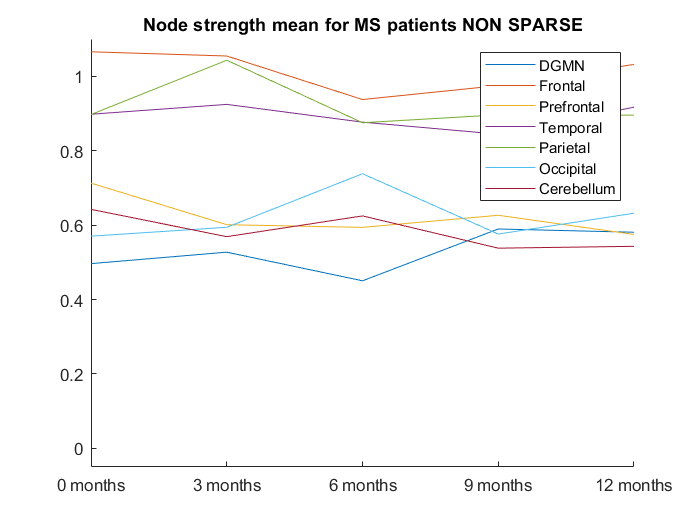

sessions = linspace(1,5,5);
sessions2 = linspace(1,2,2);

%NON SPARSE MS
figure(1); hold on;
plot(sessions,[MS_ns_mean{1,1}(1),MS_ns_mean{2,1}(1),MS_ns_mean{3,1}(1),MS_ns_mean{4,1}(1),MS_ns_mean{5,1}(1)],'-');
plot(sessions,[MS_ns_mean{1,1}(2),MS_ns_mean{2,1}(2),MS_ns_mean{3,1}(2),MS_ns_mean{4,1}(2),MS_ns_mean{5,1}(2)],'-');
plot(sessions,[MS_ns_mean{1,1}(3),MS_ns_mean{2,1}(3),MS_ns_mean{3,1}(3),MS_ns_mean{4,1}(3),MS_ns_mean{5,1}(3)],'-');
plot(sessions,[MS_ns_mean{1,1}(4),MS_ns_mean{2,1}(4),MS_ns_mean{3,1}(4),MS_ns_mean{4,1}(4),MS_ns_mean{5,1}(4)],'-');
plot(sessions,[MS_ns_mean{1,1}(5),MS_ns_mean{2,1}(5),MS_ns_mean{3,1}(5),MS_ns_mean{4,1}(5),MS_ns_mean{5,1}(5)],'-');
plot(sessions,[MS_ns_mean{1,1}(6),MS_ns_mean{2,1}(6),MS_ns_mean{3,1}(6),MS_ns_mean{4,1}(6),MS_ns_mean{5,1}(6)],'-');
plot(sessions,[MS_ns_mean{1,1}(7),MS_ns_mean{2,1}(7),MS_ns_mean{3,1}(7),MS_ns_mean{4,1}(7),MS_ns_mean{5,1}(7)],'-');
legend('DGMN','Frontal','Prefrontal','Temporal','Parietal','Occipital','Cerebellum');
title('Node strength mean for MS patients NON SPARSE');   
ylim([-0.05,1.1]);
xticks([1 2 3 4 5]);
xticklabels({'0 months','3 months', '6 months', '9 months', '12 months'});

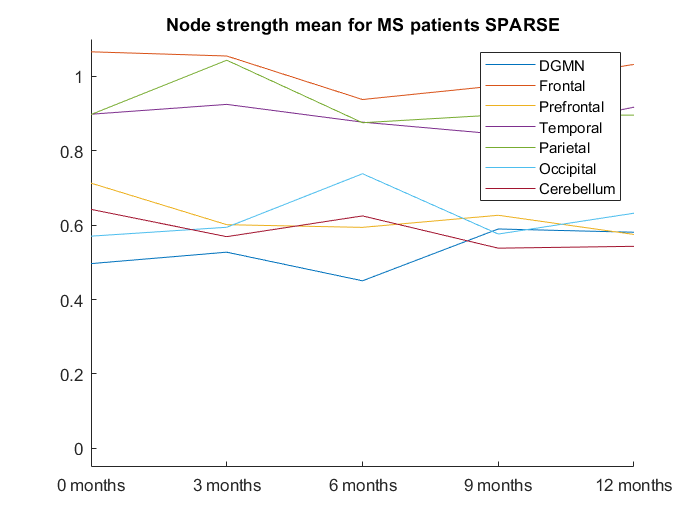


%SPARSE MS
figure(2); hold on;
plot(sessions,[MS_mean{1,1}(1),MS_mean{2,1}(1),MS_mean{3,1}(1),MS_mean{4,1}(1),MS_mean{5,1}(1)],'-');
plot(sessions,[MS_mean{1,1}(2),MS_mean{2,1}(2),MS_mean{3,1}(2),MS_mean{4,1}(2),MS_mean{5,1}(2)],'-');
plot(sessions,[MS_mean{1,1}(3),MS_mean{2,1}(3),MS_mean{3,1}(3),MS_mean{4,1}(3),MS_mean{5,1}(3)],'-');
plot(sessions,[MS_mean{1,1}(4),MS_mean{2,1}(4),MS_mean{3,1}(4),MS_mean{4,1}(4),MS_mean{5,1}(4)],'-');
plot(sessions,[MS_mean{1,1}(5),MS_mean{2,1}(5),MS_mean{3,1}(5),MS_mean{4,1}(5),MS_mean{5,1}(5)],'-');
plot(sessions,[MS_mean{1,1}(6),MS_mean{2,1}(6),MS_mean{3,1}(6),MS_mean{4,1}(6),MS_mean{5,1}(6)],'-');
plot(sessions,[MS_mean{1,1}(7),MS_mean{2,1}(7),MS_mean{3,1}(7),MS_mean{4,1}(7),MS_mean{5,1}(7)],'-');
legend('DGMN','Frontal','Prefrontal','Temporal','Parietal','Occipital','Cerebellum');
title('Node strength mean for MS patients SPARSE');
ylim([-0.05,1.1]);
xticks([1 2 3 4 5]);
xticklabels({'0 months','3 months', '6 months', '9 months', '12 months'});

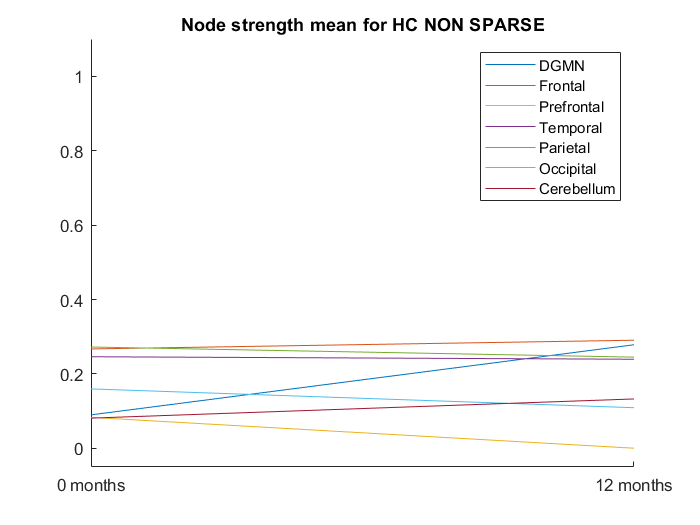


%NON SPARSE HC
figure(3); hold on;
plot(sessions2,[HC_ns_mean{1,1}(1),HC_ns_mean{2,1}(1)],'-');
plot(sessions2,[HC_ns_mean{1,1}(2),HC_ns_mean{2,1}(2)],'-');
plot(sessions2,[HC_ns_mean{1,1}(3),HC_ns_mean{2,1}(3)],'-');
plot(sessions2,[HC_ns_mean{1,1}(4),HC_ns_mean{2,1}(4)],'-');
plot(sessions2,[HC_ns_mean{1,1}(5),HC_ns_mean{2,1}(5)],'-');
plot(sessions2,[HC_ns_mean{1,1}(6),HC_ns_mean{2,1}(6)],'-');
plot(sessions2,[HC_ns_mean{1,1}(7),HC_ns_mean{2,1}(7)],'-');
legend('DGMN','Frontal','Prefrontal','Temporal','Parietal','Occipital','Cerebellum');
title('Node strength mean for HC NON SPARSE');
ylim([-0.05,1.1]);
xticks([1 2]);
xticklabels({'0 months', '12 months'});

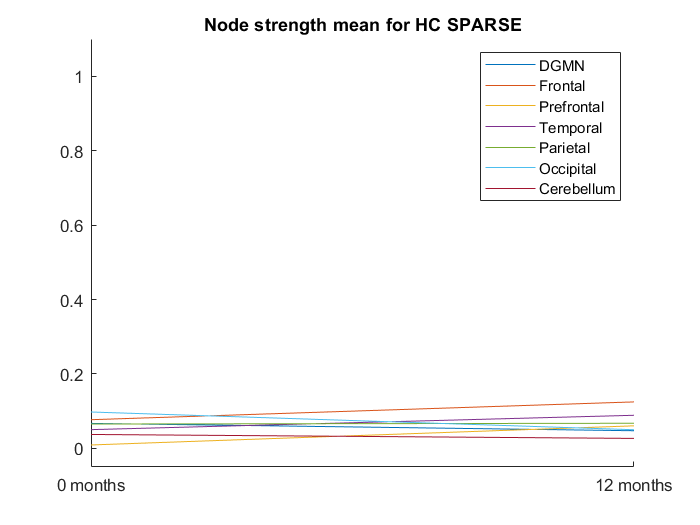


%SPARSE HC
figure(4); hold on;
plot(sessions2,[HC_mean{1,1}(1),HC_mean{2,1}(1)],'-');
plot(sessions2,[HC_mean{1,1}(2),HC_mean{2,1}(2)],'-');
plot(sessions2,[HC_mean{1,1}(3),HC_mean{2,1}(3)],'-');
plot(sessions2,[HC_mean{1,1}(4),HC_mean{2,1}(4)],'-');
plot(sessions2,[HC_mean{1,1}(5),HC_mean{2,1}(5)],'-');
plot(sessions2,[HC_mean{1,1}(6),HC_mean{2,1}(6)],'-');
plot(sessions2,[HC_mean{1,1}(7),HC_mean{2,1}(7)],'-');
legend('DGMN','Frontal','Prefrontal','Temporal','Parietal','Occipital','Cerebellum');
title('Node strength mean for HC SPARSE')
ylim([-0.05,1.1]);
xticks([1 2]);
xticklabels({'0 months', '12 months'});